## Sistemas en diferencias

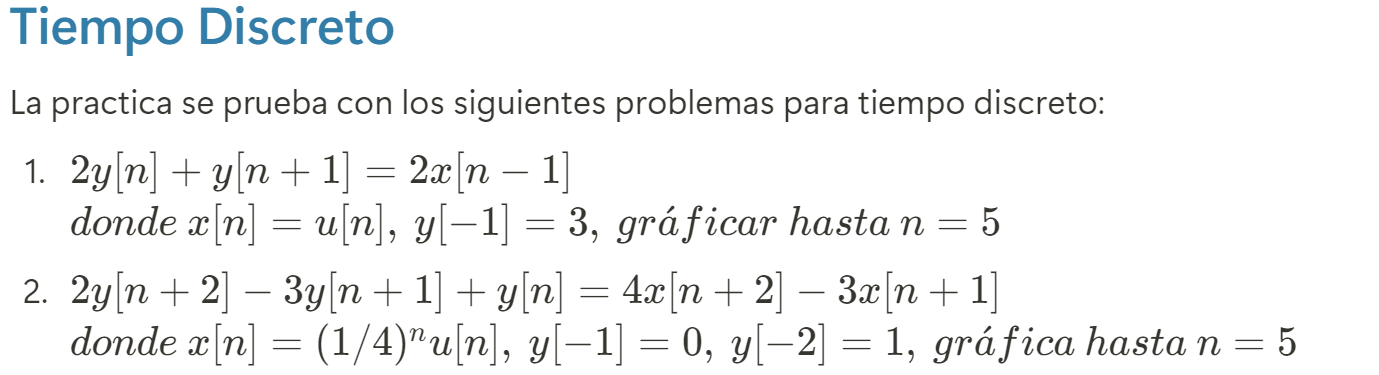

Usando

sympref('HeavisideAtOrigin', 1);

y

function zeta2016a(a,b,ciy,cix,xi,n0)
% a coeficientes de las traslaciones de la salida mayor a menor [a_n, ..., a_0]
% b coeficientes de las traslaciones de la entrada mayor a menor [b_m, ..., b_0]
% ciy condiciones iniciales de la salida de mayor a menor [y(n-1), y(0)]
% cix condiciones iniciales de la entrada de mayor a menor [x(m-1), x(0)]
% xi funcion de entrada en terminos de la variable simbolica n previamente
% declarada en el command window
% n0 tiempo final para graficar la solucion, y la entrada
% ejemplo: resolver 
%6y[n+2]+5y[n+1]+y[n]=x[n+1]+x[n] con y[1]=2 y[0]=1
%x[0]=0.5, x[n]=u[n], para 30 segundos, se resuleve como
% syms n
% zeta2016a([6 5 1],[ 1, 1],[2 1],[0.5],heaviside(n),30)
close all
tam=size(a);
tami=size(b);
syms y(n) n z Y(z) x(n) X(z) Yy fp;
syms edd edi
edd=0;
edi=0;

for i=1:tam(2)
   yd(i)=y(n+tam(2)-i);
   edd=edd+ a(i)*ztrans(yd(i));   
end


for i=1:tami(2)
   xd(i)=x(n+tami(2)-i);
   edi=edi+ b(i)*ztrans(xd(i));   
end

mensaje('APLICAMOS TRANSFORMADA ZETA ')
edd=subs(edd,ztrans(y(n),n,z), Y(z));
edi=subs(edi,ztrans(x(n),n,z), X(z));
pretty(edd)
disp('=')
pretty(edi)
mensaje('SUBSTITUIMOS CONDICIONES INICIALES')

for j=1:tami(2)-1
edi=subs(edi,x(tami(2)-1-j),cix(j));
end

for j=1:tam(2)-1
edd=subs(edd,y(tam(2)-1-j),ciy(j));
end

pretty(edd)
disp('=')
pretty(edi)

mensaje('SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA')

edi=subs(edi,X(z), ztrans(xi));
pretty(edd)
disp('=')
pretty(edi)

mensaje('DESPEJAMOS Y(z)')

edd=collect(edd,Y(z));
edd=subs(edd,Y(z),Yy);
eq1=edd==edi;
disp('Y(z)=')
edd=solve(eq1, Yy);
pretty(edd)

%%% Para versiones superiores a 2016
mensaje('DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(z)')
disp('Y(z)=')
pretty(partfrac(edd))
%%%% Si se ejecuta en 2015 o menor comentar las 3 lineas anteriores

mensaje('Aplicamos transformada inversa, asi la solucion es')
disp('y(n)=')
y(n)=iztrans(edd);
pretty(y(n))

figure (1)
hFig = figure(1);
set(hFig, 'Position', [0 0 900 900])
axes1 = axes('Parent',hFig,'FontWeight','bold','FontSize',16);
tiempo=0:1:n0;
stem(tiempo,subs(xi,n,tiempo),'b','LineWidth',2)
hold on
stem(tiempo,subs(y(n),n,tiempo),'r','LineWidth',2)
legend('Entrada x[n]','Salida y[n]','Location','Best')
xlabel('tiempo','FontWeight','bold','FontSize',16)
title('Solucion de la ecuacion en diferencias ','FontWeight','bold','FontSize',16)
grid on
end

function mensaje(texto)
disp( ' ')
disp(texto)
disp( ' ')
end

### 1. 2y[n]+y[n+1]=2x[n−1]

**2. Muestra la respuesta al impulso (simbólico, gráfica, ver KroneckerDelta)**

Como se entiende que la respuesta al impulso ocurre cuando y[-1]=0 y x[n]=δ[n], entonces tenemos:

zeta2016a([1 2],[0 2],[0 1],[0],kroneckerDelta(n),5)

 
APLICAMOS TRANSFORMADA ZETA 
 
2 Y(z) - z y(0) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS CONDICIONES INICIALES
 
2 Y(z) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
2 Y(z) + z Y(z)

=
2

 
DESPEJAMOS Y(z)
 
Y(z)=
  2
-----
z + 2

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(z)
 
Y(z)=
  2
-----
z + 2

 
Aplicamos transformada inversa, asi la solucion es
 
y(n)=
                           n
kroneckerDelta(n, 0) - (-2)



syms n

**3. Muestra la respuesta a entrada cero (simbólico, gráfica)**

syms n
zeta2016a([1 2],[0 2],[0 2],[0],heaviside(n),5)

 
APLICAMOS TRANSFORMADA ZETA 
 
2 Y(z) - z y(0) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS CONDICIONES INICIALES
 
2 Y(z) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
2 Y(z) + z Y(z)

=
  2
----- + 2
z - 1

 
DESPEJAMOS Y(z)
 
Y(z)=
    2 z
----------
 2
z  + z - 2

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(z)
 
Y(z)=
    2           4
--------- + ---------
3 (z - 1)   3 (z + 2)

 
Aplicamos transformada inversa, asi la solucion es
 
y(n)=
          n
2   2 (-2)
- - -------
3      3



**4. Muestra la respuesta a estado cero (simbólico, gráfica)**

syms n
zeta2016a([1 2],[0 2],[0 0],[1],heaviside(n),5)

 
APLICAMOS TRANSFORMADA ZETA 
 
2 Y(z) - z y(0) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS CONDICIONES INICIALES
 
2 Y(z) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
2 Y(z) + z Y(z)

=
  2
----- + 2
z - 1

 
DESPEJAMOS Y(z)
 
Y(z)=
    2 z
----------
 2
z  + z - 2

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(z)
 
Y(z)=
    2           4
--------- + ---------
3 (z - 1)   3 (z + 2)

 
Aplicamos transformada inversa, asi la solucion es
 
y(n)=
          n
2   2 (-2)
- - -------
3      3



**5. Muestra la respuesta total (simbólico, gráfica)**

syms n
zeta2016a([1 2],[0 2],[0 1],[1],heaviside(n),5)

 
APLICAMOS TRANSFORMADA ZETA 
 
2 Y(z) - z y(0) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS CONDICIONES INICIALES
 
2 Y(z) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
2 Y(z) + z Y(z)

=
  2
----- + 2
z - 1

 
DESPEJAMOS Y(z)
 
Y(z)=
    2 z
----------
 2
z  + z - 2

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(z)
 
Y(z)=
    2           4
--------- + ---------
3 (z - 1)   3 (z + 2)

 
Aplicamos transformada inversa, asi la solucion es
 
y(n)=
          n
2   2 (-2)
- - -------
3      3



**6. La respuesta total al escalón con condiciones iniciales 0 (simbólico, gráfica)**

 
APLICAMOS TRANSFORMADA ZETA 
 
2 Y(z) - z y(0) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS CONDICIONES INICIALES
 
2 Y(z) + z Y(z)

=
2 X(z)

 
SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA
 
2 Y(z) + z Y(z)

=
  2
----- + 2
z - 1

 
DESPEJAMOS Y(z)
 
Y(z)=
    2 z
----------
 2
z  + z - 2

 
DESARROLLAMOS LAS FRACCIONES PARCIALES DE Y(z)
 
Y(z)=
    2           4
--------- + ---------
3 (z - 1)   3 (z + 2)

 
Aplicamos transformada inversa, asi la solucion es
 
y(n)=
          n
2   2 (-2)
- - -------
3      3



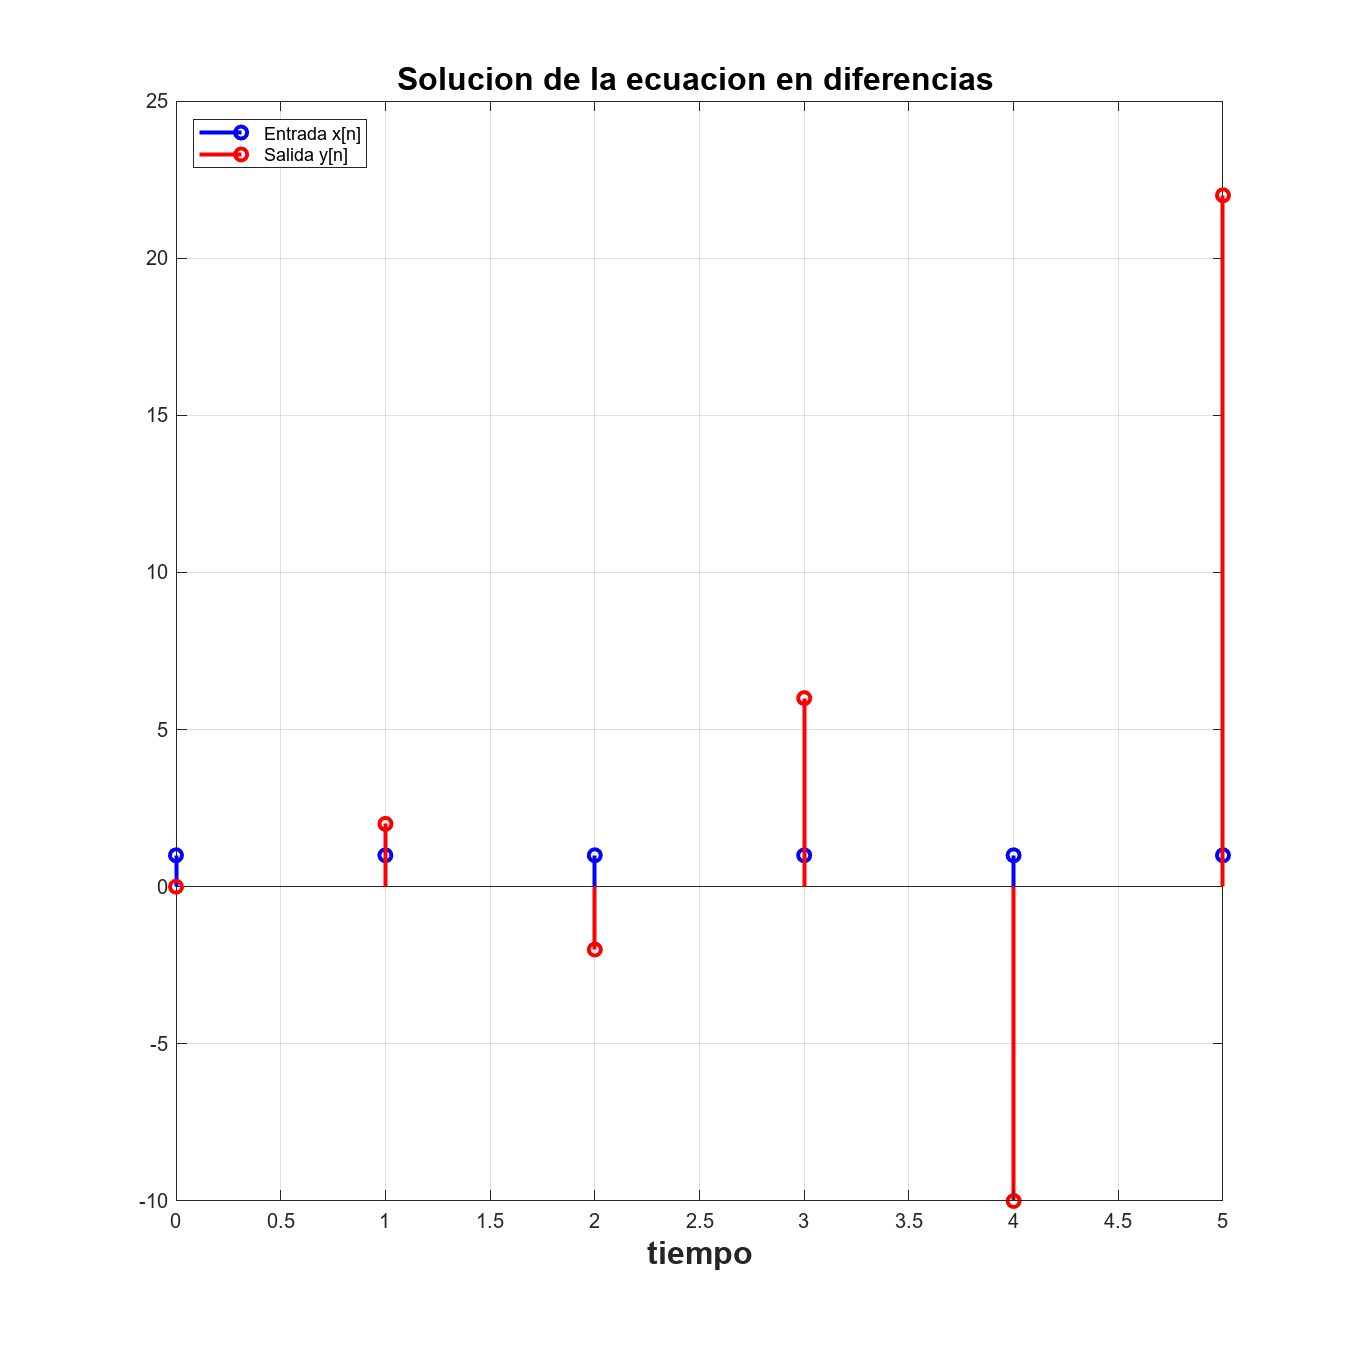

syms n
zeta2016a([1 2],[0 2],[0 1],[1],heaviside(n),5)

7. Usando subplot, depliega una figura con 5 gráficas

**1. Muestra la función de transferencia del sistema**


syms n;
sympref('HeavisideAtOrigin', 1);
msj = "Cual es el orden del sistema en diferencias a resolver?     ";
orden = input(msj);
%obteniendo a
ny = orden;
a = 1:(ny+1);
while (ny > -1)
    promt = "Ingrese el coeficiente de la traslacion "+ (ny) +" de la salida    ";
    a(1,(ny+1)) = input(promt);
    ny = ny-1;
end

%obteniendo b

nx =input(['Cual sera el orden de entrada de la ecuacion? (por favor ' ...
    'introduzca solo el numero)    ']);
b = 1:(nx+1);
while (nx > -1)
    promt = "Ingrese el coeficiente de la traslacion "+ nx +" de la entrada        ";
    b(1,(nx+1)) = input(promt);
    nx = nx-1;
end
%Recordar quien es la entrada del sistema 
xn = input('Ingrese la función que corresponde a la entrada, en formato Matlab')
tam=size(a);
tami=size(b);
syms y(n) n z Y(z) x(n) X(z) Yy fp;
syms edd edi
edd=0;
edi=0;

for i=1:tam(2)
   yd(i)=y(n+tam(2)-i);                 %% Aqui se van haciendo las iteraciones desde el orden de traslacion mayor
   edd=edd+ a(i)*ztrans(yd(i));         %% hasta el orden menor
end

for i=1:tami(2)
   xd(i)=x(n+tami(2)-i);            %%Lo mismo para la entrada
   edi=edi+ b(i)*ztrans(xd(i));   
end

mensaje('APLICAMOS TRANSFORMADA ZETA ')
edd=subs(edd,ztrans(y(n),n,z), Y(z));
edi=subs(edi,ztrans(x(n),n,z), X(z));
pretty(edd)
disp('=')
pretty(edi)

cix = input('Ingrese las conciciones iniciales de la salida de mayor a menor traslacion')
mensaje('SUBSTITUIMOS CONDICIONES INICIALES')

%obteniendo ciy
nciy = orden;
ciy = 1:nciy;
while (nciy>0)
    promt = "Cual es el valor de la condicion inicial de la "+ (nciy-1)+ " derivada?    ";
    ciy(1,nciy)= input(promt);
    nciy=nciy-1;
end
ciy2=ciy; %guardando variable para uso a futuro

msj3 = "Introduzca el tiempo t en el que quiere que la ecuacion sea " + ...
    "evaluada (le recomendamos 10)     ";
t0 = input(msj3);
xi2 = xn; %guardando la funcion original para uso a futuro

for j=1:tam(2)-1
edd=subs(edd,y(tam(2)-1-j),ciy(j));
end

pretty(edd)
disp('=')
pretty(edi)
mensaje('SUBSTITUIMOS LA TRANSFORMADA DE LA ENTRADA')

edi=subs(edi,X(z), ztrans(xi));
pretty(edd)
disp('=')
pretty(edi)

mensaje('DESPEJAMOS Y(z)')

edd=collect(edd,Y(z));
edd=subs(edd,Y(z),Yy);
eq1=edd==edi;
disp('Y(z)=')
edd=solve(eq1, Yy);
pretty(edd)
mensaje('Aplicamos la transformada z a la entrada para depsues calcular la funcion de transferencia')
xz = ztrans(xn)
disp('X(z) = ')
pretty(xz)
%Ahora calculamos la funcion de transferencia
FT = edd./xz          %edd de la linea 108 y hacemos el cociente vectorial
disp('La funcion de transferencia del sistema es: ')
pretty(FT)